# Example of solution of nonlinear algebraic equations

Code author: Dr. Robert Hesketh, [hesketh@rowan.edu](mailto:hesketh@rowan.edu)

Source: Problem 8.11 in Problem Solving in Chemical and Biochemical Engineering with POLYMATH, Excel, and MATLAB (2nd Edition), Publisher: Prentice Hall PTR; (September 22, 2007) ISBN-10: 0131482041 or ISBN-13: 978-0131482043, by Michael B. Cutlip and Mordechai Shacham.

## ChE Summer School Objectives

- Review this template which solves a system of nonlinear equations using fsolve function of MATLAB

- Save a copy of this template and perform the modifications for part c in the problem statement.  In this short exercise you will modify the function `MNLEfun `to replace $f_F = 0.005$ for a calculation of the friction factor based on $Re$ using the Shacham Equation $$$f_F = \frac{1}{{16} \left\{\log \left[\frac{\varepsilon/D}{3.7}-\frac{5.02}{Re}\log 
                                      \left(\frac{\varepsilon/D}{3.7}+\frac{14.5}{Re}\right)\right]\right\}^2}$$$

- Comment on any difficulties that you had in modifying this template

## Learning Objectives

- Solve a system of nonlinear equations.

- Derive a model of a complex pipe network where you are given a process flow diagram with all dimensions, an inlet and outlet system pressure, but not any flowrates.  Using fsolve from either MATLAB or python solve for the flowrate in each pipe segment.

- Modify this live script template to solve for parts b and c of the problem given below.

## Problem Statement

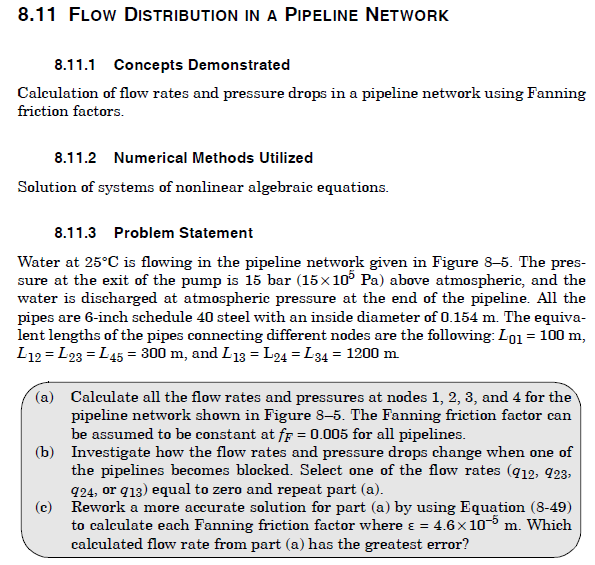

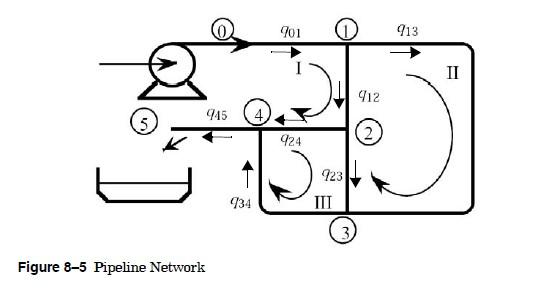

## Solution

First derive the equations that you will need for this problem.  In the picture below the distance between each intersection is given and the intersections or nodes are labeled with a number.  Next a flow direction is assumed for each pipe segment and this direction is marked with an arrow.  In this manner the pressure drops are defined by this flow direction.

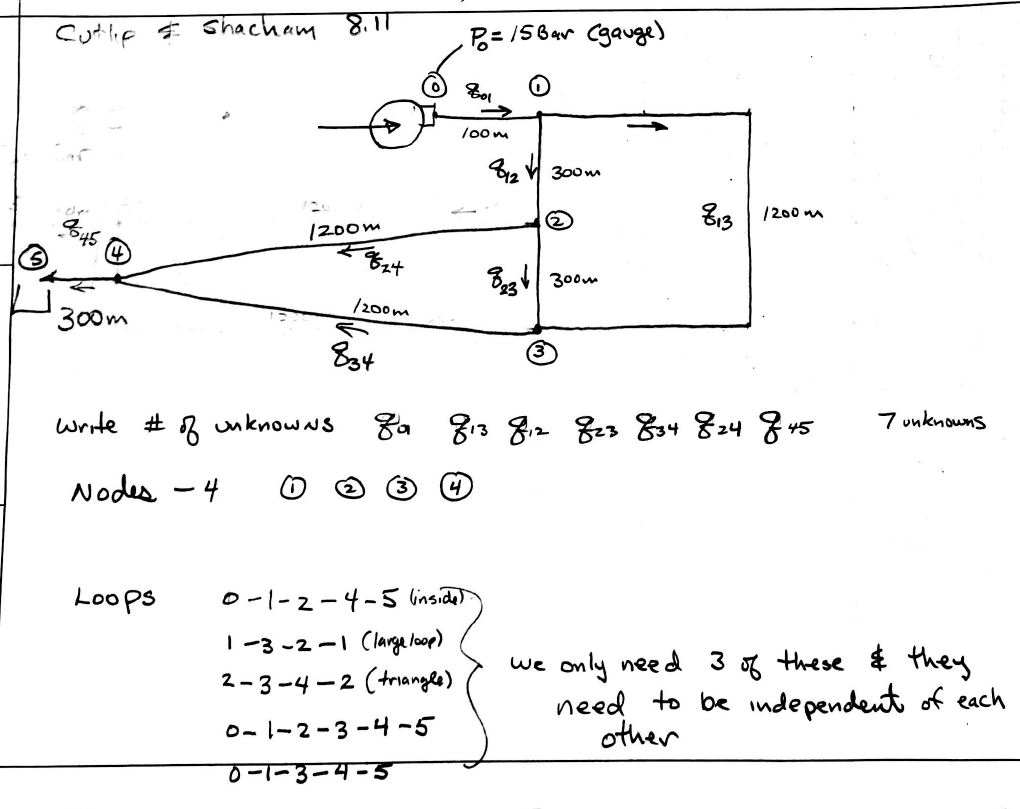

Water is flowing at 25°C.  All pipes are 6-inch Sch 40 (0.154m)

### General Mechanical Energy Balance


$$$$\frac{1}{2} \rho v_1^2+\rho g z_1+P_1+ \frac{\dot{W_s}}{q} 
= \frac{1}{2} \rho v_2^2+\rho g z_2+P_2+ \frac{2 \rho f_F v_{12}^2 L_{12}}{D}$$$$


### Shacham Equation


$$$$f_F = \frac{1}{{16} \left\{\log \left[\frac{\varepsilon/D}{3.7}-\frac{5.02}{Re}\log 
                                      \left(\frac{\varepsilon/D}{3.7}+\frac{14.5}{Re}\right)\right]\right\}^2}$$
$$



$$$$Re=\frac{\rho v_{12} D_{12}}{\mu}$$$$


In each of the pipe segments we will solve for the pressure drop as a function of the flowrate. 


$$$$\Delta P_{ij} = k_{ij}q_{ij}^2$$
$$k_{ij} = \frac{32 \rho f_{F_{ij}} \Delta L_{ij}}{\pi^2 D^5}$$$$


### Node Equations or Mass Balances


$$$$0=q_{01}-q_{12}-q_{13}$$
$$0=q_{12}-q_{24}-q_{23}$$
$$0=q_{23}+q_{13}-q_{34}$$
$$0=q_{24}+q_{34}-q_{45}$$$$


### Loop Equations


$$$$0=\Delta P_{P}+\Delta P_{01}+\Delta P_{12}+\Delta P_{24}+\Delta P_{45}$$
$$0=\Delta P_{13}-\Delta P_{23}-\Delta P_{12}$$
$$0=\Delta P_{23}+\Delta P_{34}-\Delta P_{24}$$$$


Solve the last 7 equations with appropriate support equations defined above.  

Assume for the first attempt (part a and b) that the properties of the fluid are that of water and the friction factor is a constant at $$f_F=0.005$$.  For part c you will solve part a with the friction factor given by the Shacham Equation given above.

Start by clearing the window and declaring some format options.  The `format("shortG")` displays numeric values in a compact form with 5 total digits. Numeric formats affect only how numbers appear in the display, not how MATLAB® computes or saves them.  Format compact is a line spacing format and places the lines close together.

clear, clc, format short g, format compact

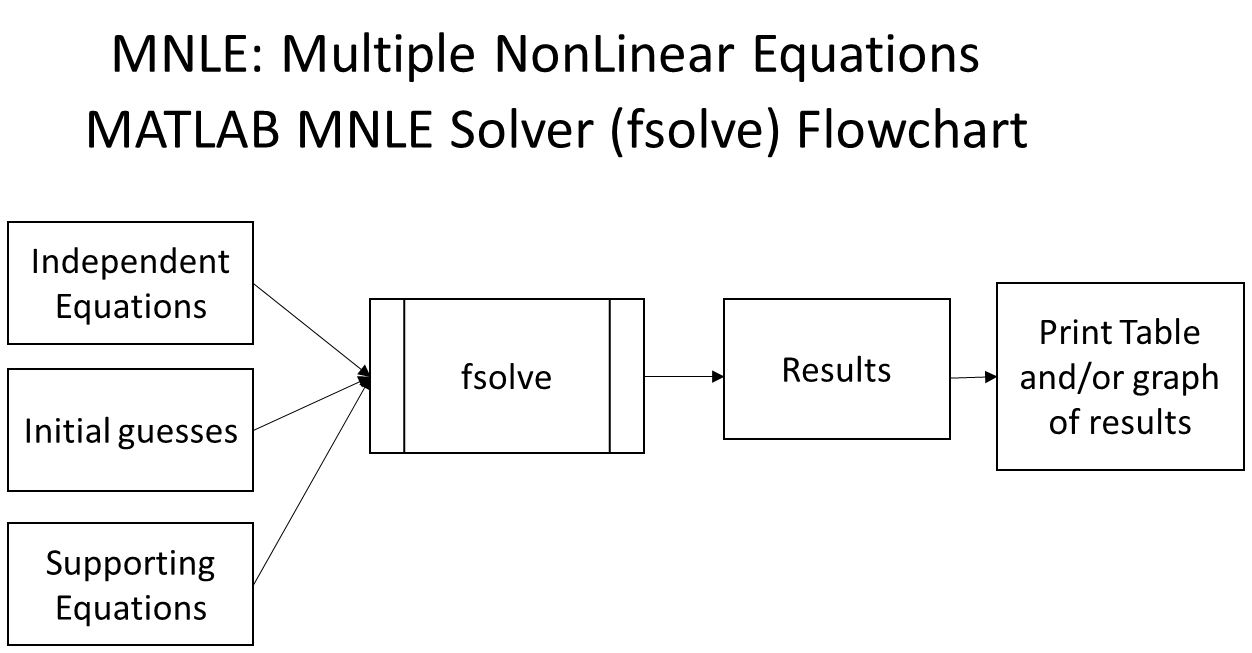

Based on the equations given above create a function that solves for the zero of each independent equation.  A picture of this function is given below, but the actual code is at the end of this live script.  

The cell below defines the set of nonlinear equations that we derived above. This is put into a function so that we can use this many times.

To find the flowrates we will use the MATLAB function called `fsolve`. To use fsolve we will call the function containing all the equations and give it initial guesses for each flowrate. These initial flowrates are put into a vector `x`. The non-linear equations are rearranged so that 0 = f(x).  So, if you plugged in each `x` into these equations, you would like them all to be zero or some small value like <1E-6.  ($$1\times 10^{-6}$$) The value obtained from plugging in the flowrates are stored in a vector` fx.` The program (`fsolve`) will check to see if each of these values is less than 1E-6.  If they are the program stops.  If not, then a complex root finding method starts and goes through many iterations.  This completes the required input for fsolve. The other variables $f_F, \rho, D, pi, k's$ are used in the nonlinear equations and need to be defined before the variable is used in the nonlinear equation.

If you get the following message:  'fsolve' requires [Optimization Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'OP', 'focused', 'fsolve');).  You will need to install this package and then restart your computer.

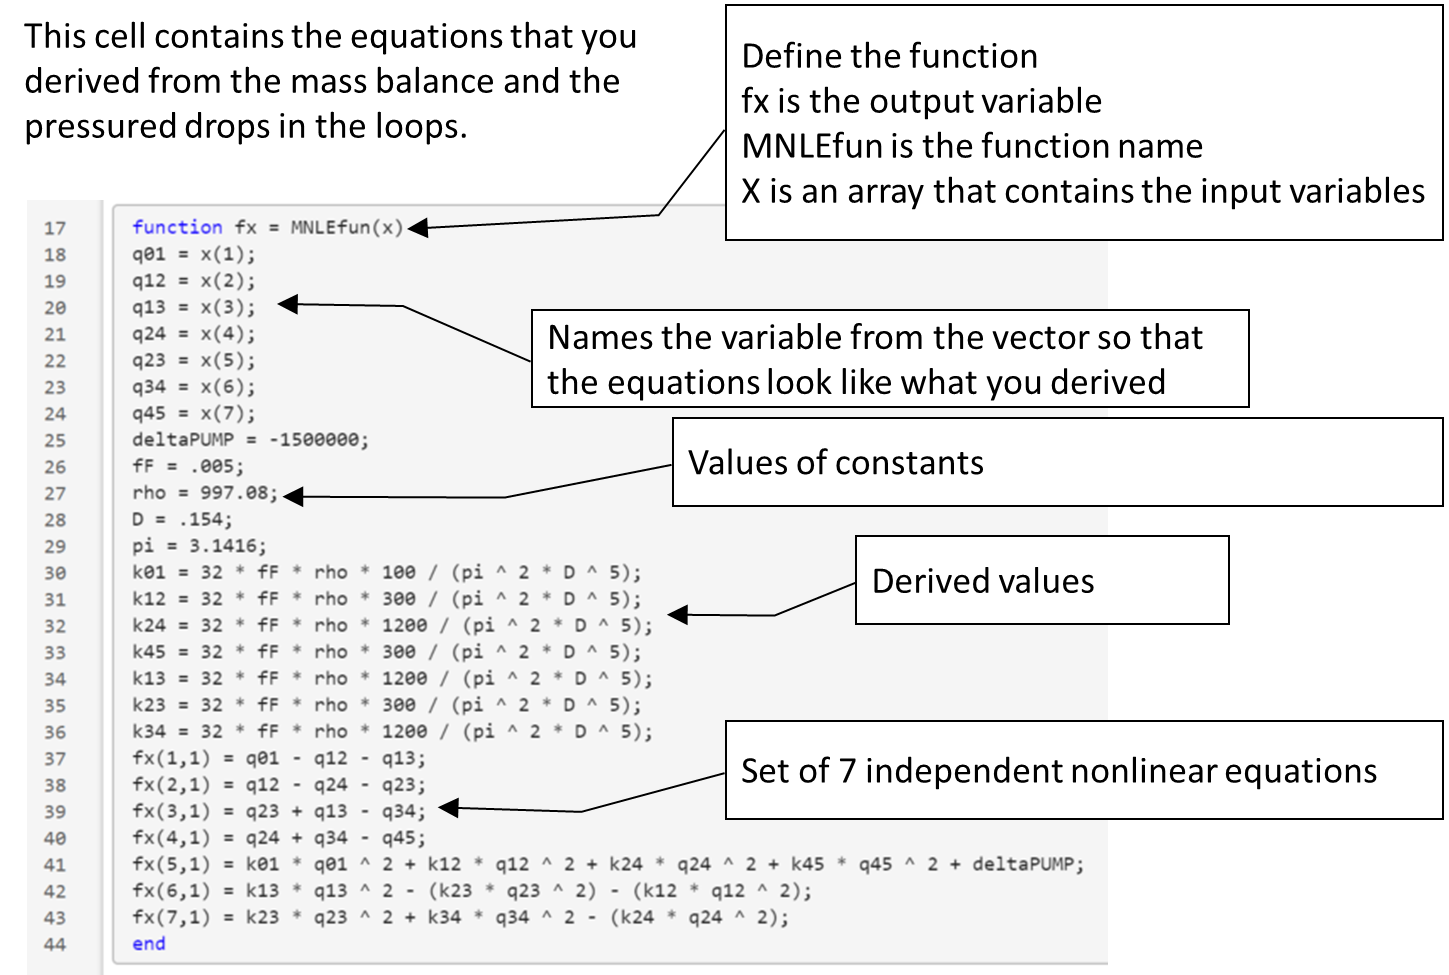

### Initial Estimates

In the cell below I test to make sure the function is working. Each of these equations can be tested separately by hand or using an excel spreadsheet.

`fsolve` required an array for input so the line 8 in the cell below `x=np.array([q01,q12,q13,q23,q24,q34,q45])` creates this array.

The print commands show the values input and then calculated from the input. It is always a good idea to test your functions to see if they work!

q01=  0.0981369;
q12=  0.0648196;
q13 = 0.0333174; 
q23  =0.0154472; 
q24  =0.0493724; 
q34  =0.0487645; 
q45  =0.0981369;

xguess = [q01 q12 q13 q23 q24 q34 q45]; % values that should be close to the final answer

fguess=MNLEfun(xguess);

for i=1:size(xguess,2);
    if i==1
        disp(' Variable        Value            Function Value')
    end
disp([' x' int2str(i) '                 ' num2str(xguess(i)) '            ' num2str(fguess(i))]);
end

 Variable        Value            Function Value


 x1                 0.098137            -1e-07
 x2                 0.06482            6.9389e-18
 x3                 0.033317            0.033925
 x4                 0.015447            -0.033925
 x5                 0.049372            -492436.7062
 x6                 0.048765            -123110.9403
 x7                 0.098137            615553.9456


So, where did these guesses come from? Did the professor know the answer?  If he did, he got the last 3 flowrates wrong! In most problems, you will not have a solution. So, how do you estimate a q? One way to do this is assume that all the flow goes through path 0-1-3-4-5 which is the longest path.

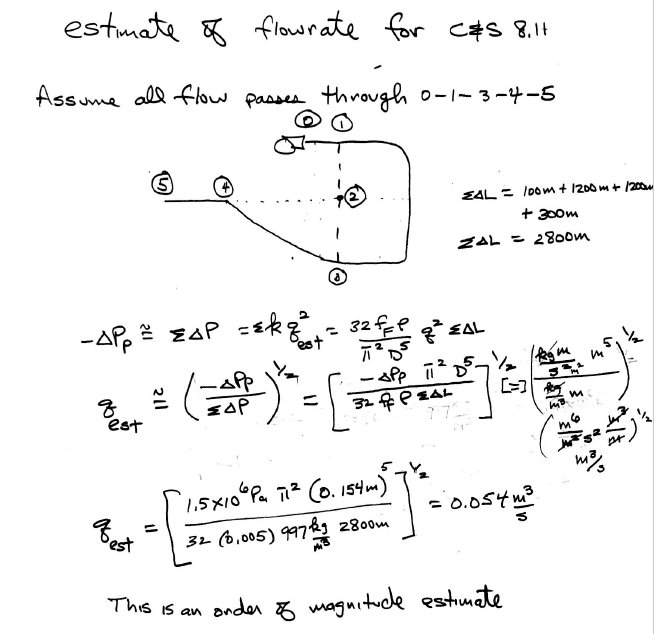


$$$$\Delta P_{ij} = k_{ij}q_{ij}^2$$
$$k_{ij} = \frac{32 \rho f_{F} \Delta L_{total}}{\pi^2 D^5}$$$$


One big Loop Equation


$$$$0=\Delta P_{P}+\Delta P_{01}+\Delta P_{12}+\Delta P_{45}$$$$


Solve for


$$$$q_{estimate}^2=\frac {-\Delta P_{P}} {\frac{32 \rho f_F \Delta L_{total}}{\pi^2 D^5}}$$$$


Remember this is bad math!  It is only used to find an order of magnitude estimate because we know that not all the fluid flows in this outer loop.

deltaPUMP = -1500000; 
fF = 0.005; 
rho = 997.08; 
D = 0.154; 
Ltotal=100+1200++1200+300

Ltotal =         2800

k = 32 * fF * rho * 100 / (pi ^ 2 * D ^ 5)*Ltotal

k =    5.2252e+10

qest=((-deltaPUMP*pi^2*D^5)/(32*fF*rho*Ltotal))^0.5

qest =      0.053579

So, our initial estimate for all the q's will be 0.05 $m^3/s$

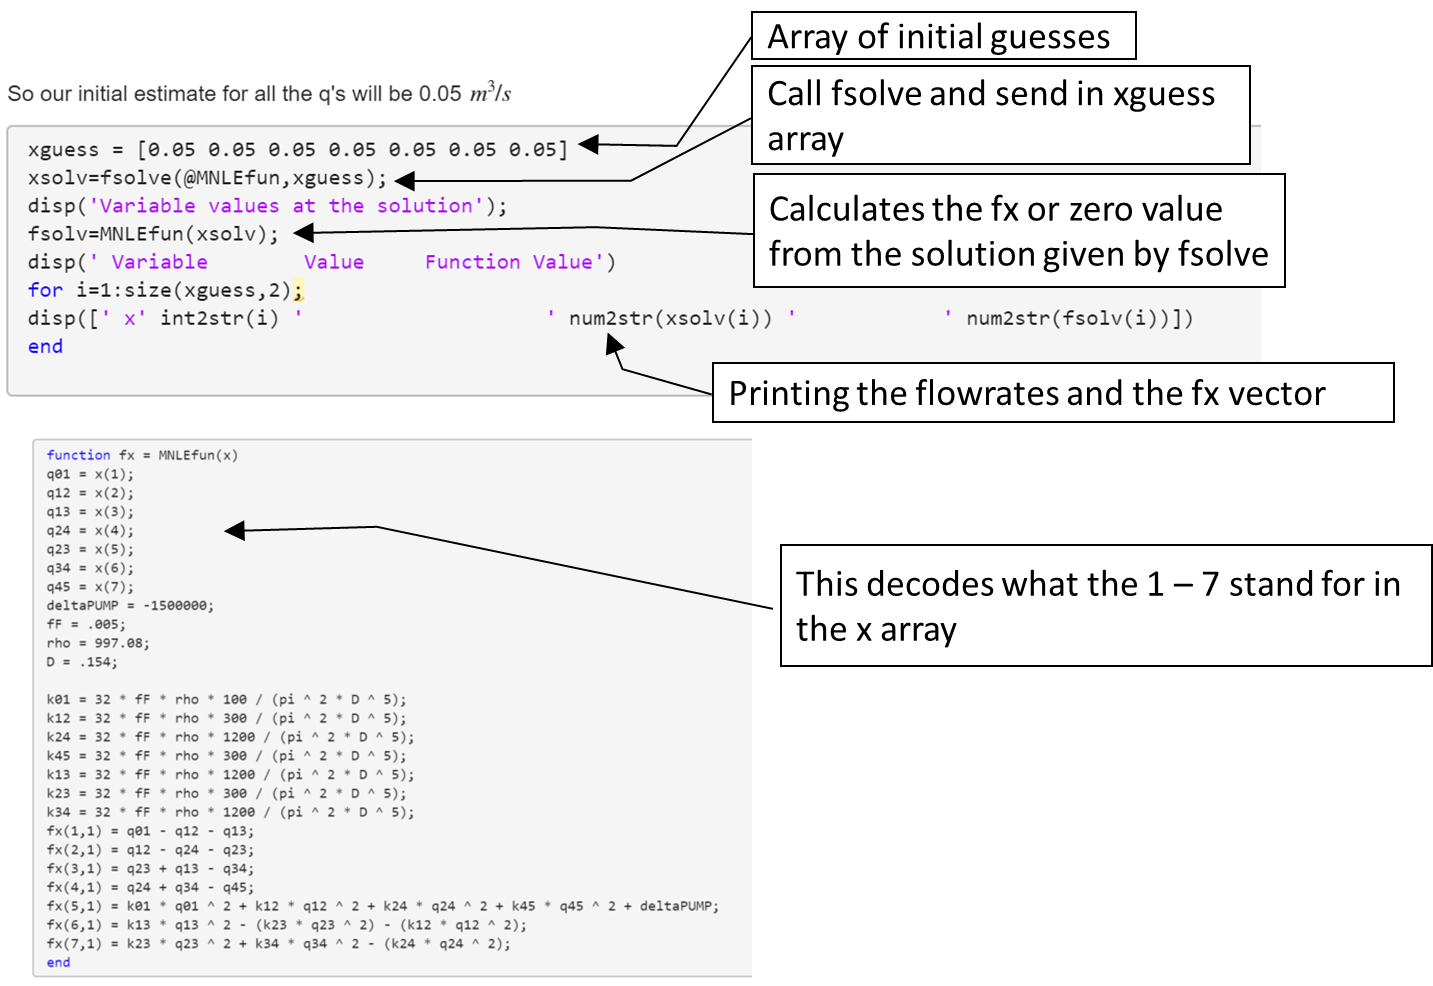

### First Solution

xguess = [0.05 0.05 0.05 0.05 0.05 0.05 0.05];
xsolv=fsolve(@MNLEfun,xguess); 


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


fsolv=MNLEfun(xsolv);
for i=1:size(xguess,2);
    if i==1
        disp('Variable values at the solution');
        disp(' Variable        Value               Function Value')
    end
    disp(['     x' int2str(i) '         ' num2str(xsolv(i)) '            ' num2str(fsolv(i))])
end

Variable values at the solution


 Variable        Value               Function Value


     x1         0.098137            0
     x2         0.064819            1.7347e-18
     x3         0.033317            6.9389e-18
     x4         0.049372            -1.3878e-17
     x5         0.015447            0
     x6         0.048764            0
     x7         0.098137            1.1642e-10


This is very good, although the word stalled at first appears to be bad, but upon reading it stopped iterating when all the `fx`'s were less than the function tolerance!

[`Equation solved, solver stalled`](matlab: helpview('optim','eqn_solved_singular','CSHelpWindow');)`.`

`fsolve stopped because the relative `[`size of the current step`](matlab: helpview('optim','norm_current_step','CSHelpWindow');)` is less than the`

`value of the `[`step size tolerance`](matlab: helpview('optim','step_size_tol','CSHelpWindow');)` squared and the vector of function values`

`is near zero as measured by the value of the `[`function tolerance`](matlab: helpview('optim','fcn_tolerance_fsolve','CSHelpWindow');)`.`

`<`[`stopping criteria details`](matlab: createExitMsg({'optim:fsolve:Exit2basic','fsolve'},{'optim:fsolve:Exit2detailed','fsolve','9.262500e-18','1.000000e-12','8.470329e-22','1.000000e-03'},true,true);;)`>`

`Variable values at the solution`

` Variable               Value               Function Value`

` x1                    0.098137            0`

` x2                    0.06482            3.4694e-18`

` x3                    0.033317            6.9389e-18`

` x4                    0.049372            0`

` x5                    0.015447            0`

` x6                    0.048765            -2.9104e-11`

` x7                    0.098137            0`

Notice that the solution only gives `x1, x2, x3` etc.  To communicate to the professor or anyone else looking at this problem you will need to make a table that identifies the flowrate for each q!

If more stringent tolerances are required, then the cell below gives an example of declaring higher tolerances.  The defaults are `TolFun=1e-6, TolX=1e-6.`

`See `[`folve tolerances`](https://www.mathworks.com/help/optim/ug/fsolve.html#:~:text=Termination%20tolerance%20on%20the%20function,The%20default%20is%201e%2D6%20.)

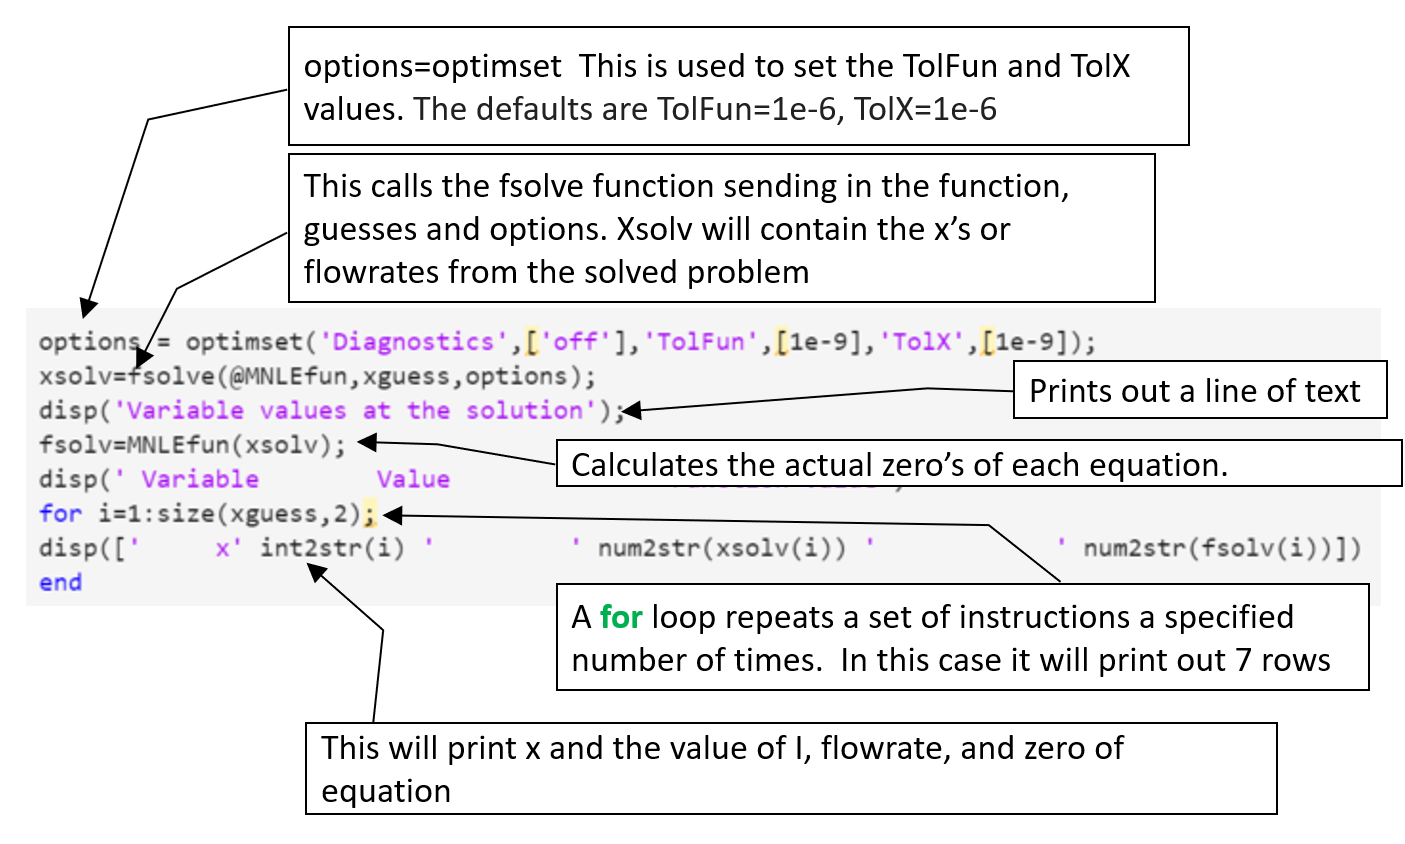

### Final Solution with Refined Tolerances

options = optimset('Diagnostics',['off'],'TolFun',[1e-9],'TolX',[1e-9]); 
xsolv=fsolve(@MNLEfun,xguess,options); 


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


fsolv=MNLEfun(xsolv);
for i=1:size(xguess,2);
    if i==1
        disp('Variable values at the solution');
        disp(' Variable        Value               Function Value')
    end
disp(['     x' int2str(i) '         ' num2str(xsolv(i)) '            ' num2str(fsolv(i))])
end

Variable values at the solution


 Variable        Value               Function Value


     x1         0.098137            0
     x2         0.064819            1.7347e-18
     x3         0.033317            6.9389e-18
     x4         0.049372            -1.3878e-17
     x5         0.015447            0
     x6         0.048764            0
     x7         0.098137            1.1642e-10


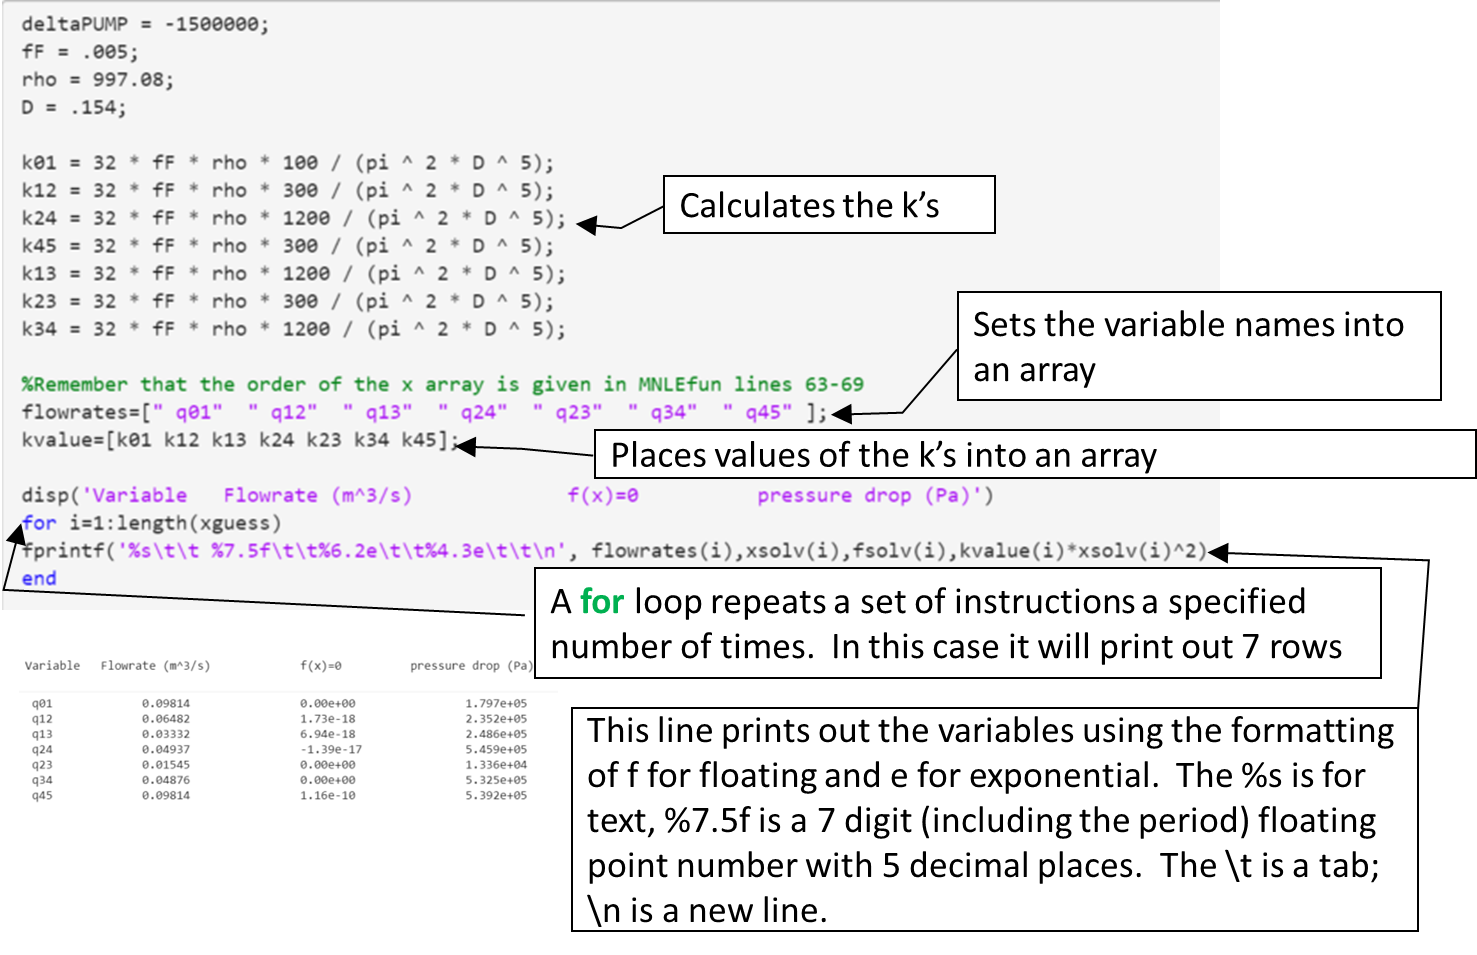

More information on the fprintf command can be found [here](https://www.mathworks.com/help/matlab/ref/fprintf.html).

The table is given below

deltaPUMP = -1500000; 
fF = .005; 
rho = 997.08; 
D = .154; 

k01 = 32 * fF * rho * 100 / (pi ^ 2 * D ^ 5); 
k12 = 32 * fF * rho * 300 / (pi ^ 2 * D ^ 5); 
k24 = 32 * fF * rho * 1200 / (pi ^ 2 * D ^ 5); 
k45 = 32 * fF * rho * 300 / (pi ^ 2 * D ^ 5); 
k13 = 32 * fF * rho * 1200 / (pi ^ 2 * D ^ 5); 
k23 = 32 * fF * rho * 300 / (pi ^ 2 * D ^ 5); 
k34 = 32 * fF * rho * 1200 / (pi ^ 2 * D ^ 5); 
 
%Remember that the order of the x array is given in MNLEfun lines 63-69
flowrates=[" q01"  " q12"  " q13"  " q24"  " q23"  " q34"  " q45" ];
kvalue=[k01 k12 k13 k24 k23 k34 k45];
for i=1:length(xguess)
    if i==1
        disp('Variable   Flowrate (m^3/s)             f(x)=0          pressure drop (Pa)')
    end
fprintf('%s\t\t %7.5f\t\t%6.2e\t\t%4.3e\t\t\n', flowrates(i),xsolv(i),fsolv(i),kvalue(i)*xsolv(i)^2)
end

Variable   Flowrate (m^3/s)             f(x)=0          pressure drop (Pa)


 q01		 0.09814		0.00e+00		1.797e+05		
 q12		 0.06482		1.73e-18		2.352e+05		
 q13		 0.03332		6.94e-18		2.486e+05		
 q24		 0.04937		-1.39e-17		5.459e+05		
 q23		 0.01545		0.00e+00		1.336e+04		
 q34		 0.04876		0.00e+00		5.325e+05		
 q45		 0.09814		1.16e-10		5.392e+05		


The summary table of flowrates and pressure drops for part a

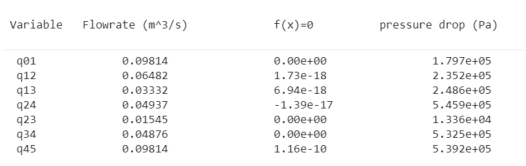

## Student Exercise

Now revise this template and solve parts b and c of the problem repeated below.  For part c use the Shacham Equation for $f_F$ given above and repeated here $$$f_F = \frac{1}{{16} \left\{\log \left[\frac{\varepsilon/D}{3.7}-\frac{5.02}{Re}\log 
                                      \left(\frac{\varepsilon/D}{3.7}+\frac{14.5}{Re}\right)\right]\right\}^2}$$$

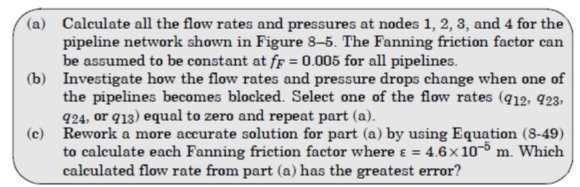

## Functions

function fx = MNLEfun(x) 
q01 = x(1); 
q12 = x(2); 
q13 = x(3); 
q24 = x(4); 
q23 = x(5); 
q34 = x(6); 
q45 = x(7); 
deltaPUMP = -1500000; 
fF = .005; 
rho = 997.08; 
D = .154; 

k01 = 32 * fF * rho * 100 / (pi ^ 2 * D ^ 5); 
k12 = 32 * fF * rho * 300 / (pi ^ 2 * D ^ 5); 
k24 = 32 * fF * rho * 1200 / (pi ^ 2 * D ^ 5); 
k45 = 32 * fF * rho * 300 / (pi ^ 2 * D ^ 5); 
k13 = 32 * fF * rho * 1200 / (pi ^ 2 * D ^ 5); 
k23 = 32 * fF * rho * 300 / (pi ^ 2 * D ^ 5); 
k34 = 32 * fF * rho * 1200 / (pi ^ 2 * D ^ 5); 
fx(1,1) = q01 - q12 - q13; 
fx(2,1) = q12 - q24 - q23; 
fx(3,1) = q23 + q13 - q34; 
fx(4,1) = q24 + q34 - q45; 
fx(5,1) = k01 * q01 ^ 2 + k12 * q12 ^ 2 + k24 * q24 ^ 2 + k45 * q45 ^ 2 + deltaPUMP; 
fx(6,1) = k13 * q13 ^ 2 - (k23 * q23 ^ 2) - (k12 * q12 ^ 2); 
fx(7,1) = k23 * q23 ^ 2 + k34 * q34 ^ 2 - (k24 * q24 ^ 2); 
end